## Problem 8

 Using the following rectangular form for the DFT equation:

                                                        
$$X\left(m\right)=\sum_{n=0}^{N-1} x\left(n\right)\left\lbrack \mathrm{cos}\left(2\pi \frac{\mathrm{nm}}{N}\right)-\mathrm{jsin}\left(2\pi \frac{\mathrm{nm}}{N}\right)\right\rbrack$$


(a) Prove that the fs/2 spectral sample is X(N/2) = N · sin(θ) when the x(n) input is a sinusoidal sequence defined by 

                                                                x(n) = sin[2π(fs/2)nts + θ]. 

N is an even number, frequency fs is the x(n) sequence’s sample rate in Hz, time index n = 0, 1, 2, ..., N−1, and θ is an initial phase angle measured in radians. 

Hint: Recall the trigonometric identity sin(α+β) = sin(α)cos(β) + cos(α)sin(β). 

(b) What is X(N/2) when x(n) = sin[2π(fs/2)nts]? 

(c) What is X(N/2) when x(n) = cos[2π(fs/2)nts]? 

**Answer:**

**(a)**

**Correspons to half the sample rate. **

**(b)**

**X(N/2) is fsample/N**

**(c) **

**X(N/2) is 0**

## Problem 9

To gain some practice in using the algebra of discrete signals and the geometric series identities in Appendix B, and to reinforce our understanding of the output magnitude properties of a DFT when its input is an exact integer number of sinusoidal cycles: 

(a) Prove that when a DFT’s input is a complex sinusoid of magnitude Ao (i.e., x(n) = Aoej2πfnts) with exactly three cycles over N samples, the output magnitude of the DFT’s m = 3 bin will be |X(3)| = AoN. Hint: The first step is to redefine x(n)’s f and ts variables in terms of a sample rate fs and N so that x(n) has exactly three cycles over N samples. The redefined x(n) is then applied to the standard DFT equation. 

(b) Prove that when a DFT’s input is a real-only sinewave of peak amplitude Ao (i.e., x(n) = Aosin(2πfnts)) with exactly three cycles over N samples, the output magnitude of the DFT’s m = 3 bin will be |X(3)| = AoN/2. 

Hint: Once you redefine x(n)’s f and ts variables in terms of a sample rate fs and N so that x(n) has exactly three cycles over N samples, you must convert that real sinewave to complex exponential form so that you can evaluate its DFT for m = 3. 

The purpose of this problem is to remind us that DFT output magnitudes are proportional to the size, N, of the DFT. That fact is important in a great many DSP analysis activities and applications. 

**Answers:**

**(a) 3/f = N**$t_s$

    **f**$t_s$ = **3/N**

**    x[n] = **$A_0 e^{2\pi n\frac{3}{n}}$

    **x[k] = **$\sum_{n=0}^{N-1} x\left\lbrack n\right\rbrack$$e^{-j\pi \frac{\mathrm{kn}}{N}}$

    **x(n) = **${\sum_{n=0}^{N-1} A}_0 e^{2\pi n\frac{3}{n}}$ * $e^{-j\pi \frac{\mathrm{kn}}{N}}$ =  A$e^{\mathrm{j2}\pi \frac{n}{N}\left(3-k\right)}$

 **   x(3) = A**$e^{j*0}$**=**$\Sigma$** A = NA**

**(b)**

 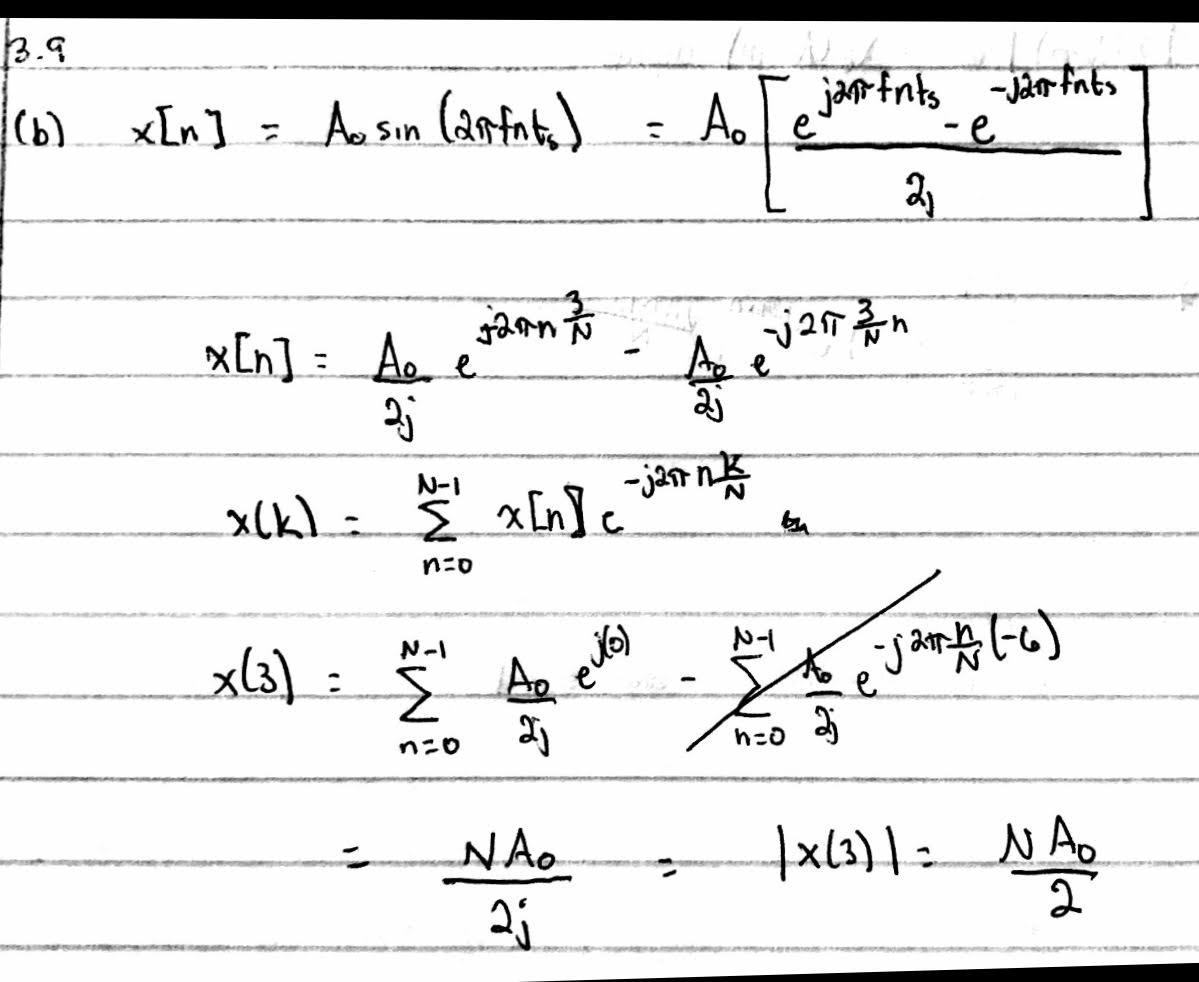

## Problem 10

Consider performing the 5-point DFT on the following x1(n) time-domain samples 

x1(n) = [1, 2.2, −4, 17, 21], 

and the DFT’s first sample is X1(0) = 37.2. Next, consider performing the 5-point DFT on the following x2(n) time samples 

x2(n) = [1, 2.2, −4, 17, Q], 

and that DFT’s first sample is X2(0) = 57.2. What is the value of Q in the x2(n) time sequence? Justify your answer. 

**Answer:**

**Q = 41. Because X(0) is the sum of x(n) samples we can calculate Q by just subtracting X2(0) with x2(n) samples**

x1 = [1, 2.2, -4, 17, 21];
sum(x1)

ans = 37.2000

Q = 57.2 - 1 - 2.2 + 4 - 17

y = 41

## Problem 11

Derive the equation describing X(m), the N-point DFT of the following x(n) sequence:

 x(n) = a^n,            for 0 ≤ n ≤ N−1.

Hint: Recall one of the laws of exponents, p^bq^(bc) = (pq^c)^b, and the geometric series identities in Appendix B. 

**Answer:**

## Problem 12

Consider an N-sample x(n) time sequence whose DFT is represented by X(m), where 0 ≤ m ≤ N −1. Given this situation, an Internet website once stated, “The sum of the X(m) samples is equal to N times the first x(n) sample.” Being suspicious of anything we read on the Internet, show whether or not that statement is true. 

Hint: Use the inverse DFT process to determine the appropriate x(n) time sample of interest in terms of X(m). 

**Answer:**

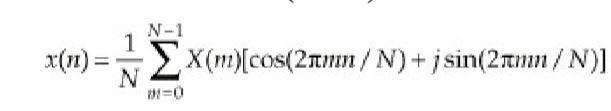

**Using the inverse sample and looking back on of the example problems in the book 3.1.1 and using the results from DFT Example 1 into Eq. (3-23), we’ll go from the frequency domain back to the time domain and get our original real Eq. (3-11′) x(n) sample values of**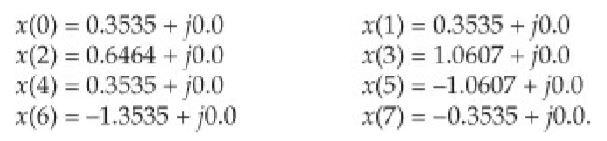

**We already that the sum of these samples is 0 and since N is 8 and the 1st x(n) sample is 0.3535, we now know that this statement is NOT true. **

## Problem 13

Here is a problem whose solution may be useful to you in the future. On the Internet you will find information suggesting that an inverse DFT can be computed using a forward DFT software routine in the process shown in Figure P3-13. 

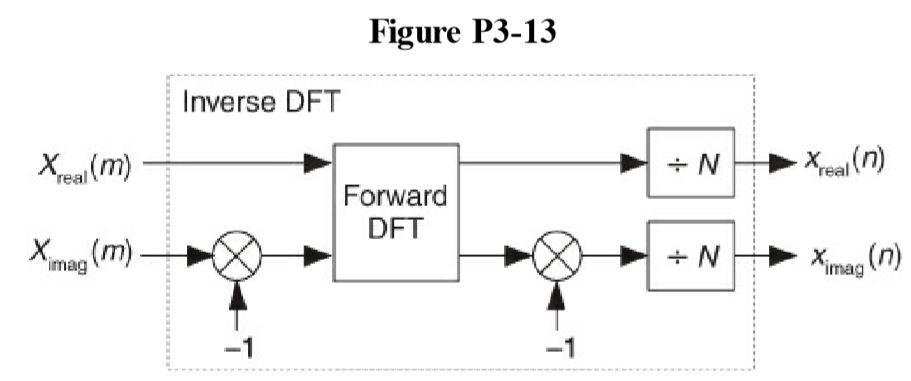

(a) Using the forward and inverse DFT equations, and the material in Appendix A, show why the process in Figure P3-13 computes correct inverse DFTs. Hint: Begin your solution by writing the inverse DFT equation and conjugating both sides of that equation. 

(b) Comment on how the process in Figure P3-13 changes if the original frequency-domain X(m) sequence is conjugate symmetric. 

**Answer:**

**DFT:   **$X\left(k\right)=\sum_{n=0}^{N-1} {x_n e}^{\frac{-\textrm{j2}\pi }{N}\textrm{kn}}$

            
$$x\left(\omega \right)=\sum_{n=-\infty }^{\infty } x\left(n\right)\;e^{-j\omega n}$$


**IDFT: **$X\left(n\right)=\frac{1}{N}\sum_{m=0}^{N-1} {X\left(m\right)e}^{\frac{j\left(2\pi \textrm{nm}\right)}{N}}$

           
$$x\left(n\right)=\frac{1}{N}\;\sum_{k\;=\;0}^{N-1} x\left(k\right)e^{\frac{\left(\textrm{j2}\pi \textrm{nk}\right)}{N}} \;$$


Complex Conjugate:


$$x\left(n\right)\longleftrightarrow x\left(-k*\textrm{mod}\;N\right)$$



$$x\left(-n*\textrm{mod}\;N\right)\longleftrightarrow x\left(k\right)$$


Proven through:

 
$$x\left(k\right)=x\left(-k*\textrm{mod}\;N\right)$$



$$X\left(k\right)=\sum_{n=0}^{N-1} {x\left(n\right)e}^{\frac{-\textrm{j2}\pi }{N}\left(-k\;\textrm{modN}\right)n}$$


         
$$=\sum_{n=0}^{N-1} {x\left(n\right)e}^{\frac{-\textrm{j2}\pi }{N}\left(\textrm{kn}\right)}$$



$$X\left(-k\;\mathrm{mod}\;N\right)=X\left(k\right)$$


## Problem 14

One useful way to test the performance of commercial analog-to-digital (A/D) converters is to digitize an fo Hz analog sinewave, apply the N-sample x(n) sequence to a DFT, and examine the DFT’s X(m) results. The process is depicted in Figure P3-14. An ideal (A/D) converter will produce X(m) results showing spectral energy at fo Hz and no spectral energy at any other frequency. As such, nonzero spectral energy in X(m) at frequencies other than fo Hz indicates realworld A/D converter performance. However, the DFT’s inherent property of leakage “smears” spectral energy over multiple X(m) samples, as was shown in the text’s Figure 3-8(b), which degrades the effectiveness of this A/D converter test method. What can we do to minimize the DFT’s inherent spectral leakage as much as possible for this type of converter testing? 

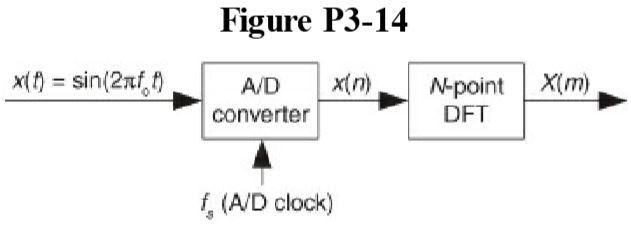

**Answer: **

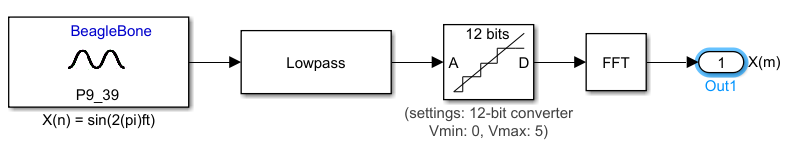

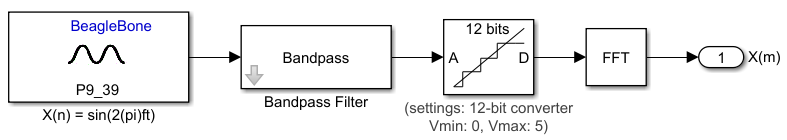

We can use sampling methods shown in chapter 2, such as lowpass filtering and Bandpass filtering.